## Image segmentation using region growing

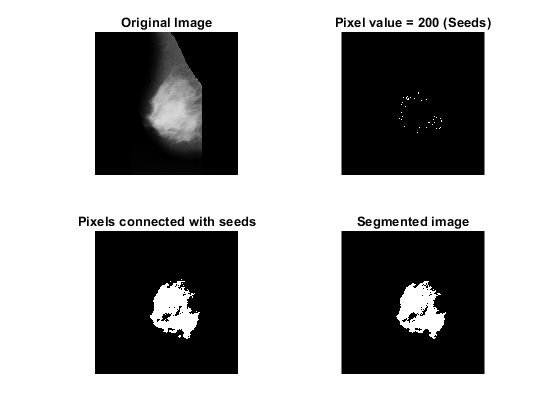

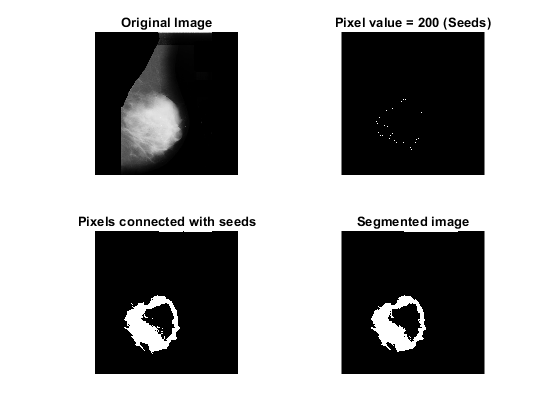

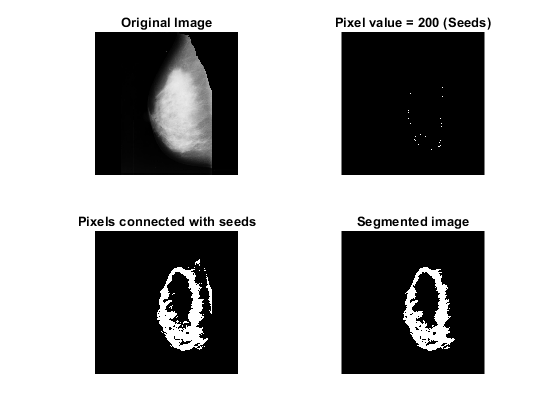

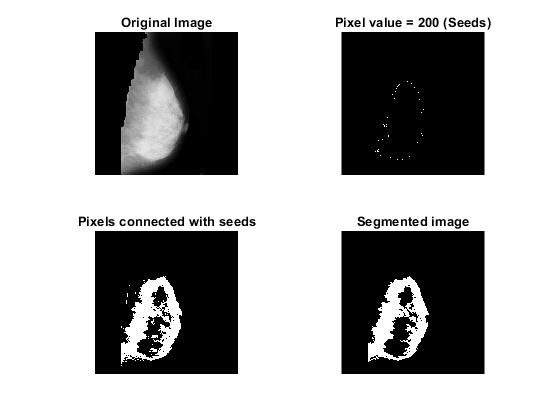

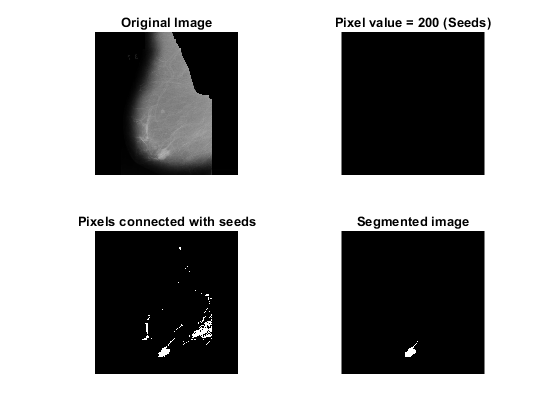

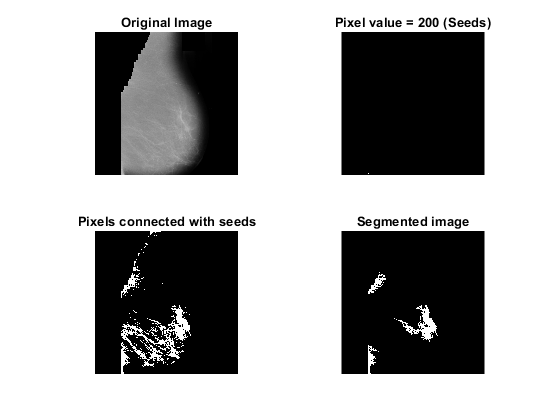

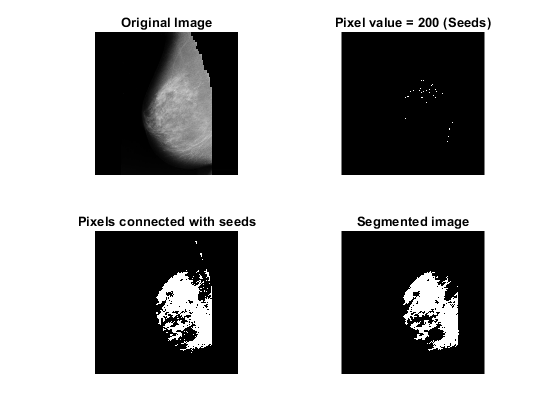

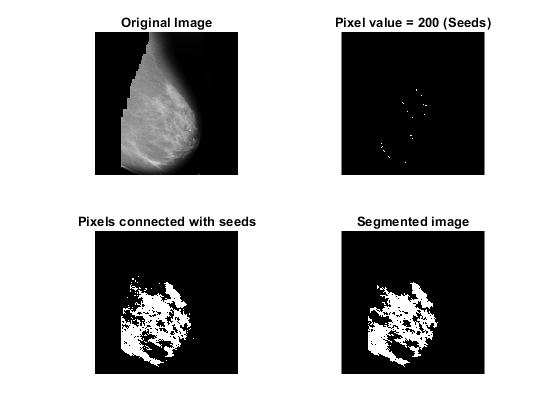

%img="new/mdb001.tiff";

%put images file location here
breastImds = imageDatastore(...
    "C:\Users\Daniel Kee\Documents\Monash\FYP\FIT3162\fit3162\Code\MIAS(no muscle)");
%img="MIAS(no muscle)/mdb020.jpg";

%loop through the images
while(hasdata(breastImds))
    I = read(breastImds);
    I = rgb2gray(I);

    I = double(I);
    figure, subplot(2,2,1),imshow(uint8(I)),title('Original Image');
    Seeds = [180];
    SI = I == Seeds;
    subplot(2,2,2), imshow(SI, []),title('Pixel value = 200 (Seeds)');
    T = 30;
    TI = false(size(I));

    for i = 1:length(Seeds)
        seed_val = Seeds(i);
        S = abs(I-seed_val) <= T;
        TI = TI | S;
    end

    subplot(2,2,3), imshow(TI, []),title('Pixels connected with seeds');
    IM = imreconstruct(SI,TI);
    subplot(2,2,4), imshow(IM, []),title('Segmented image');
end